# Ramsey

## Load data

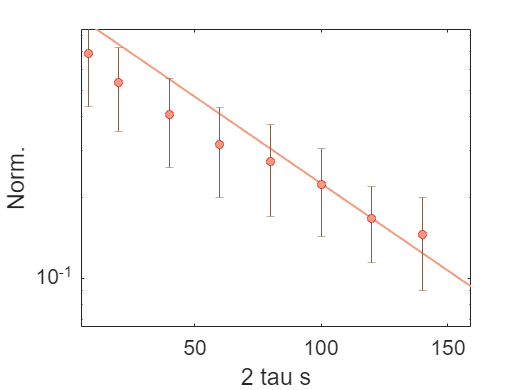

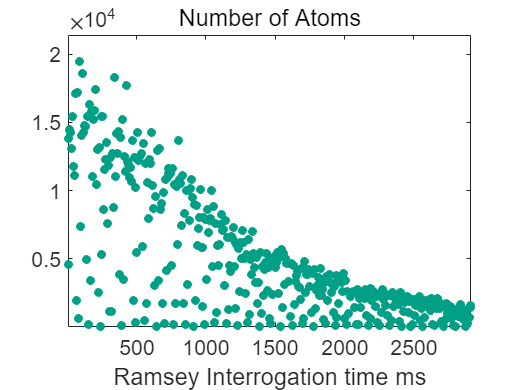

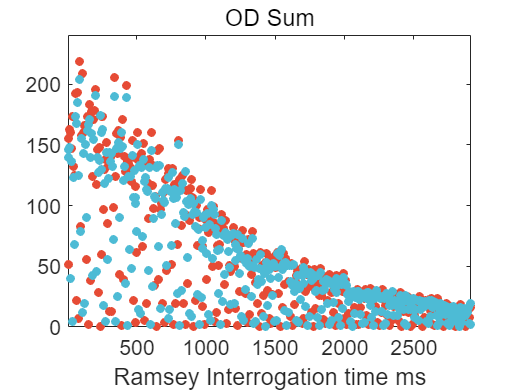

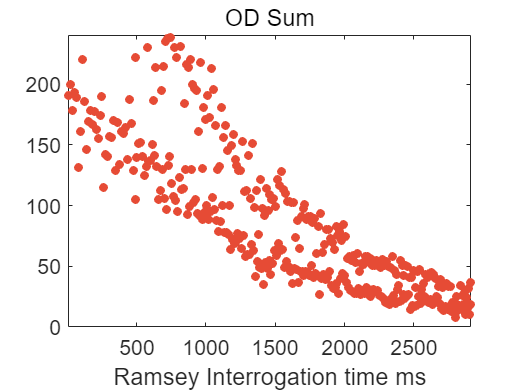

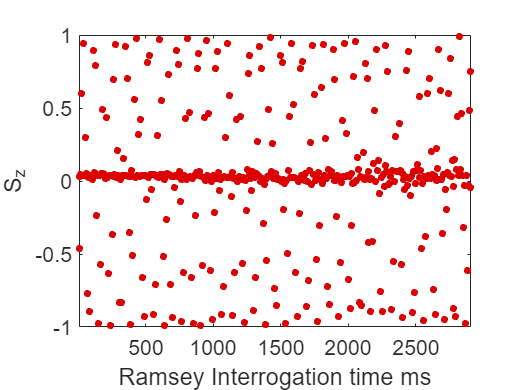

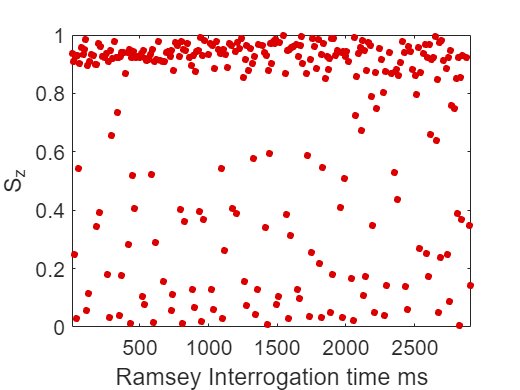

clear all
% Yb-173 Ramsey 180:20:0s 6 ms + 0:7:210 ms
main_dir='\\Artemis-pc\e\Data\2022-10-04\Abs-3612';
load([main_dir,'\average.mat'],'precess_1_list','precess_2_list','mean_1','std_1','weight_1','amp_list','amp_error','amp_weight','matrix_1','fi_result','precess_1_list','precess_1_list_plot');

% Yb-173 Ramsey FFT 1

main_dir='\\Artemis-pc\e\Data\2022-11-21\Abs-3075';
load([main_dir,'\FFT.mat'],'f','P1');
f_1=f;
P_1=P1;

% Yb-173 Ramsey FFT 2
main_dir='\\Artemis-pc\e\Data\2022-10-16\Abs-3453';
load([main_dir,'\FFT.mat'],'f','P1');
f_2=f;
P_2=P1;

% Yb-173 Ramsey number decay
% cat state
main_dir='\\Artemis-pc\e\Data\2022-11-20\Abs-1923';
load([main_dir,'\VacuumDecay.mat'],'xlist','ratio','ratio_std','');

% coherent state
main_dir='\\Artemis-pc\e\Data\2022-10-16\Abs-3453';
load([main_dir,'\RamseyDecay.mat'],'time_list_mean','OD_2_mean','OD_2_std');



## Population  decay

colors=npg(100); 

% cat state

eqn='a*exp(-x^2/b^2)';
startpoints=[1 500];
lower=[0.8 100];
upper=[1 2000];

fi=fit(xlist',ratio',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./ratio_std.^2);
f1=figure;
h2=plot((1:1:200),fi(1:1:200),'LineWidth',2,'Color',colors(5,:));
hold on
h3=errorbar(xlist',ratio,ratio_std,'o');

xlim([0 200])
ylim([0 1.1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')
ylabel('$\mathrm{Population\ on \pm 5/2}$','Interpreter','latex')

h2.Color=colors(12,:);

h3.MarkerSize=6;
h3.Color=colors(31,:);
h3.MarkerEdgeColor=colors(31,:);
h3.MarkerFaceColor=colors(12,:);
h3.CapSize=0;

ax1=gca;

fi

fi =      常规模型:
     fi(x) = a*exp(-x^2/b^2)
     系数(置信边界为 95%):
       a =      0.9933  (0.9575, 1.029)
       b =        1738  (-6031, 9507)

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans = 1.0e+03 *

    0.0000    3.8847



% coherent state

eqn='a*exp(-x^1/b^1)+(1-a)';
startpoints=[0.5 5];
lower=[0 0 ];
upper=[1 20];

fi=fit(time_list_mean',OD_2_mean',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./OD_2_std.^2);

fi

fi =      常规模型:
     fi(x) = a*exp(-x^1/b^1)+(1-a)
     系数(置信边界为 95%):
       a =      0.5795  (0.5669, 0.5922)
       b =       5.673  (5.108, 6.239)

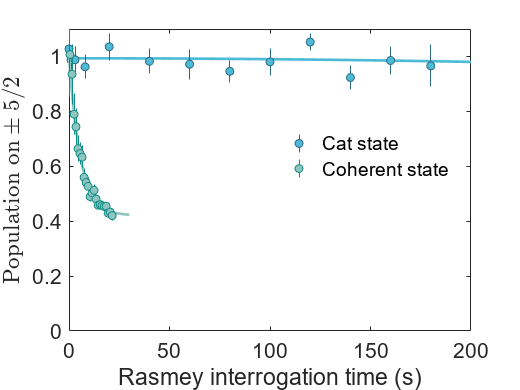

h2_1=plot((0:0.1:30),fi(0:0.1:30),'LineWidth',2,'Color',colors(5,:));

hold on

h3_1=errorbar(time_list_mean,OD_2_mean,OD_2_std,'o');

h2_1.Color=colors(65,:);
h3_1.MarkerSize=6;
h3_1.Color=colors(26,:);
h3_1.MarkerEdgeColor=colors(26,:);
h3_1.MarkerFaceColor=colors(65,:);
h3_1.CapSize=0;

legend([h3,h3_1],{'Cat state','Coherent state'},'Position',[0.6 0.55 0.2 0.1])
legend('boxoff')

print(gcf, ['\\Artemis-pc\e\Data\DataForPub','\PopulationDecay.png'],'-r300','-dpng');



% coherent state

%set(gca,'YScale','log')

## Ramsey decay

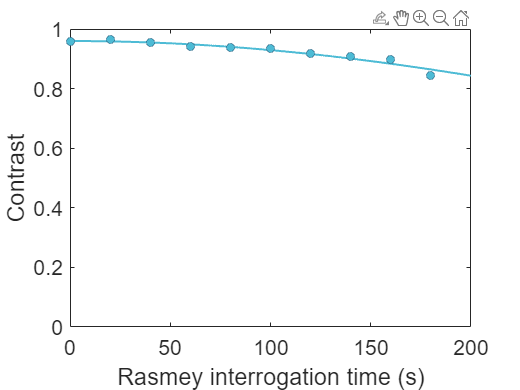

colors=npg(100); 

eqn='a*exp(-x^2/b^2)';
startpoints=[1 500];
lower=[0.8 100];
upper=[1 1000];

fi=fit(precess_2_list',amp_list,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',amp_weight);
f1=figure;
h2=plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(precess_2_list',amp_list,amp_error,'o');

xlim([0 200])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')
%ylabel('$\mathrm{Contrast}$','Interpreter','latex')

h2.Color=colors(12,:);

h3.MarkerSize=6;
h3.Color=colors(31,:);
h3.MarkerEdgeColor=colors(31,:);
h3.MarkerFaceColor=colors(12,:);
h3.CapSize=0;


ax1=gca;

fi.b

ans = 556.1316

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0040   32.1937


## FFT Plot

### Yb-173 FFT

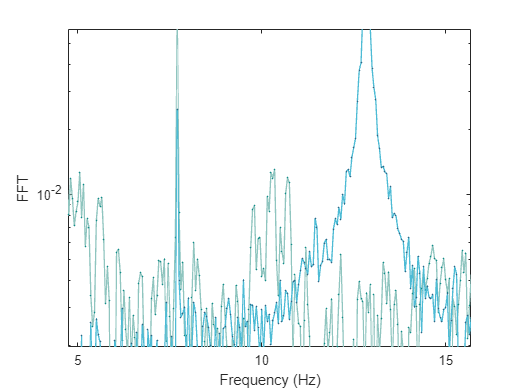

f2=figure;
plot(f_2,P_2,'Linewidth',1,'Color',colors(65,:)) 
hold on
plot(f_2,P_2,'.','Color',colors(26,:),'MarkerSize',2) 

plot(f_1,P_1,'Linewidth',1,'Color',colors(12,:)) 
hold on
plot(f_1,P_1,'.','Color',colors(31,:),'MarkerSize',2) 

xlim([0 20])
ylim([0.003 2])
set(gca,'FontSize',10)
set(gca,'YScale','log')
xlabel('Frequency (Hz)')
ylabel('FFT')

## Subplot

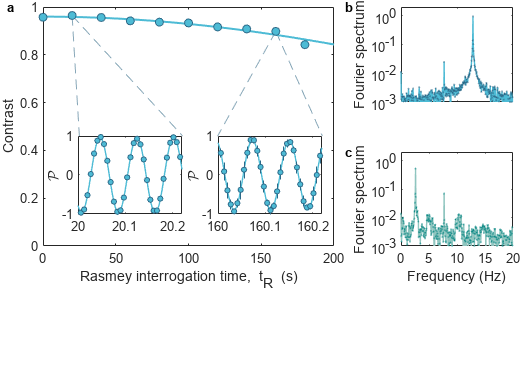

figure
t = tiledlayout(3,3,'TileSpacing','compact','Padding','tight');

%Plot 1
nexttile(1,[2 2]);

% line indicator
line([precess_2_list(9) 25],[amp_list(9) 0.46],'LineStyle',"--",'Color',colors(60,:))
line([precess_2_list(9) 96],[amp_list(9) 0.46],'LineStyle',"--",'Color',colors(60,:))

line([precess_2_list(2) 120],[amp_list(2) 0.46],'LineStyle',"--",'Color',colors(60,:))
line([precess_2_list(2) 192],[amp_list(2) 0.46],'LineStyle',"--",'Color',colors(60,:))
hold on

h2=plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(precess_2_list',amp_list,amp_error,'o');

box on
xlim([0 200])
ylim([0 1])
set(gca,'FontSize',10)
%xlabel('$Rasmey interrogation time, t_{R} (s)$','Interpreter','latex')
xlabel('Rasmey interrogation time, \it t_{R} \rm (s)')
ylabel('Contrast')
%ylabel('$\mathrm{Contrast}$','Interpreter','latex')

h2.Color=colors(12,:);

h3.MarkerSize=6;
h3.Color=colors(31,:);
h3.MarkerEdgeColor=colors(31,:);
h3.MarkerFaceColor=colors(12,:);
h3.CapSize=0;

ax1=gca;

text(-25,1,'a','FontWeight','bold')





% Plot 2
nexttile(3);
plot(f_1,P_1,'Linewidth',1,'Color',colors(12,:)) 
hold on
plot(f_1,P_1,'.','Color',colors(31,:),'MarkerSize',2) 

xlim([0 20])
ylim([0.001 2])
set(gca,'FontSize',10)
set(gca,'YScale','log')
xlabel('Frequency (Hz)')
ylabel('Fourier spectrum')

set(gca,'XLabel',[])
set(gca,'XTickLabel',[])

yticks([0.001 0.01,0.1,1])
yticklabels({'10^{-3}','10^{-2}','10^{-1}','10^{0}'})



text(-10,2,'b','FontWeight','bold')

% Plot 3
nexttile(6);
plot(f_2,P_2,'Linewidth',1,'Color',colors(65,:)) 
hold on
plot(f_2,P_2,'.','Color',colors(26,:),'MarkerSize',2) 

xlim([0 20])
ylim([0.001 2])
set(gca,'FontSize',10)
set(gca,'YScale','log')
xlabel('Frequency (Hz)')
ylabel('Fourier spectrum')
xticks([0 100 200])
xticklabels({'160','160.1','160.2'})
set(gca,'XTickLabelRotation',0)

xticks([0 5 10 15 20])
xticklabels({'0','5','10','15','20'})
set(gca,'XTickLabelRotation',0)

yticks([0.001 0.01,0.1,1])
yticklabels({'10^{-3}','10^{-2}','10^{-1}','10^{0}'})

text(-10,2,'c','FontWeight','bold')

% Sub sub figure 1
h_2=axes('Position',[0.15 0.45 0.2 0.2]);
fit_2=fi_result{9};
h2=plot(precess_1_list_plot,fit_2(precess_1_list_plot),'LineWidth',1);
hold on
h3=errorbar(precess_1_list,mean_1(:,:,9),std_1(:,:,9),'o');
xlim([0 220])
ylim([-1 1])
set(gca,'FontSize',10)
%xlabel('t (ms)')
ylabel('$\mathcal{P}$','Interpreter','latex','Position',[-30 0])

xticks([0 100 200])
xticklabels({'20','20.1','20.2'})

h2.Color=colors(12,:);

h3.MarkerSize=4;
h3.Color=colors(31,:);
h3.MarkerEdgeColor=colors(31,:);
h3.MarkerFaceColor=colors(12,:);
h3.CapSize=0;

% Sub sub figure 2
h_2=axes('Position',[0.42 0.45 0.2 0.2]);
fit_2=fi_result{2};
h2=plot(precess_1_list_plot,fit_2(precess_1_list_plot),'LineWidth',1);
hold on
h3=errorbar(precess_1_list,mean_1(:,:,2),std_1(:,:,2),'o');
xlim([0 220])
ylim([-1 1])
set(gca,'FontSize',10)
%xlabel('t (ms)')
ylabel('$\mathcal{P}$','Interpreter','latex','Position',[-30 0])

xticks([0 100 200])
xticklabels({'160','160.1','160.2'})
set(gca,'XTickLabelRotation',0)

h2.Color=colors(12,:);

h3.MarkerSize=4;
h3.Color=colors(31,:);
h3.MarkerEdgeColor=colors(31,:);
h3.MarkerFaceColor=colors(12,:);
h3.CapSize=0;



saveas(t,['\\Artemis-pc\e\Data\DataForPub','\Figure2_0.png'])
print(gcf, ['\\Artemis-pc\e\Data\DataForPub','\Figure2_1.png'],'-r300','-dpng');